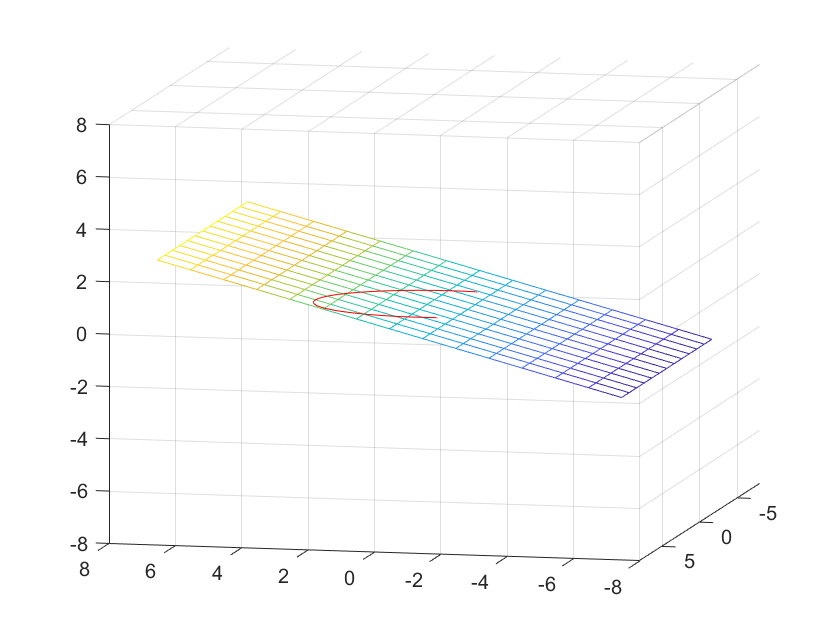

clc;clear;
hold on
axis([-8 8 -8 8 -8 8]);
axis on
grid on
view(3);
a = 3;
b = 4;

c = 5;
x = -a-3:a+3;
y = -b-3:b+3;
[X,Y] = meshgrid(x,y);
[m,n] = size(X);
Z = zeros(size(X));
for j=1:m
    Z(j,:) = Z(j,:)+(j-m/2)/3;
end

for i = 1:100
    if abs(Z(i))<=c
        
        h = mesh(X,Y,Z);
        k = sqrt(1-(Z(i)).^2/c.^2);
        Theta1 = linspace(0,2*pi,50);
        X1 = a*k.*cos(Theta1);
        Y1 = b*k.*sin(Theta1);
        Z1 = zeros(length(X1));
        g = plot3(X1,Y1,Z1,'r');
    else
        break
    end
%%    F(i) = getframe;
    
end

%%movie(F,2,30)
hold on